# Analytic Hierarchy Process

In determining which job offer to accept, Jane is choosing between the offers by determining how well each one meets the following four objectives:

- **Objective 1 **High starting salary (SAL)

- **Objective 2** Quality of life in city where job is located (QL)

- **Objective 3 **Interest in work (IW)

- **Objective 4 **Job location near family and relatives (NF)

When multiple objectives are important to a decision maker, it may be difficult to choose between alternatives. For example, one job offer may offer the highest starting salary, but it may score poorly on the other three objectives. Another job offer may meet objectives 2–4 but have a low starting salary. In such a case, it may be difficult for Jane to choose between job offers. The **analytic hierarchy process (AHP)** provides a powerful tool that can be used to make decisions in situations involving multiple objectives.

## Obtaining Weights for Each Objective

Suppose there are n objectives. We begin by writing down an $n\times n$ matrix (known as the pairwise comparison matrix) $\mathbf{A}$. The entry in row $i$ and column $j$ of $\mathbf{A}$ (call it $a_{\textrm{ij}}$) indicates how much more important objective $i$ is than objective $j$. “Importance” is to be measured on an integer-valued 1–9 scale, with each number having the interpretation shown in **Table 1**. For all $i$, it is necessary that $a_{\textrm{ii}} =1$. **If, for example, **$a_{13} =3$**, objective 1 is weakly more important than objective 3.** If $a_{\textrm{ij}} =k$, then for consistency, it is necessary that $a_{\textrm{ji}} =\frac{1}{k}$. Thus, if $a_{13} =3$, then $a_{31} =\frac{1}{3}$ must hold.

**Table 1: **Interpretation of Entries in a Pairwise Comparison Matrix

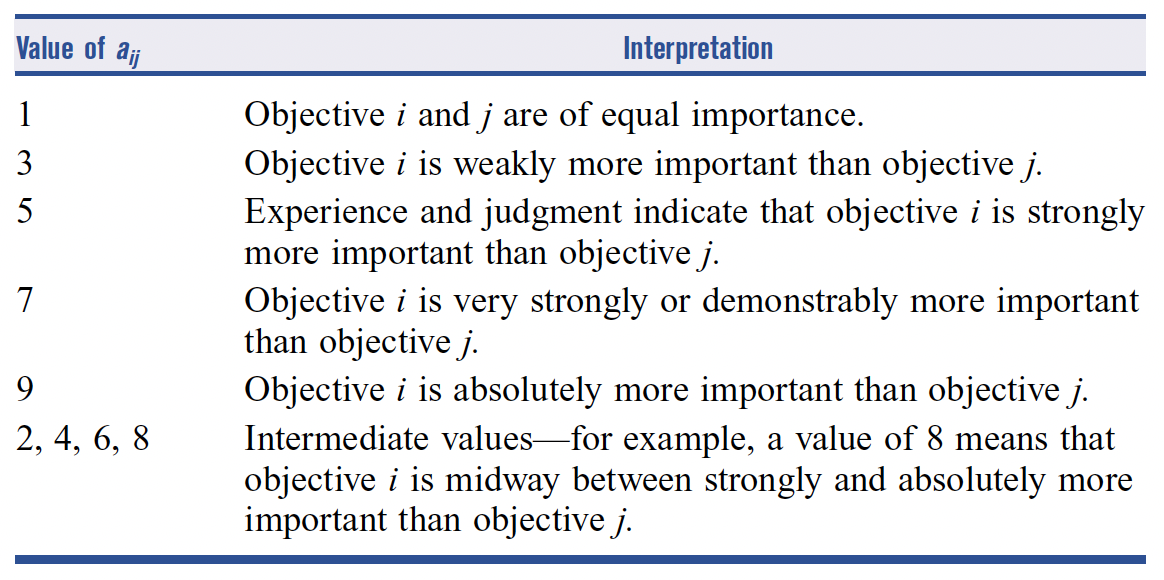

Suppose that Jane has identified the following pairwise comparison matrix for her four objectives (SAL = high salary; QL = high quality of life; IW = interest in work; NF = nearness to family):

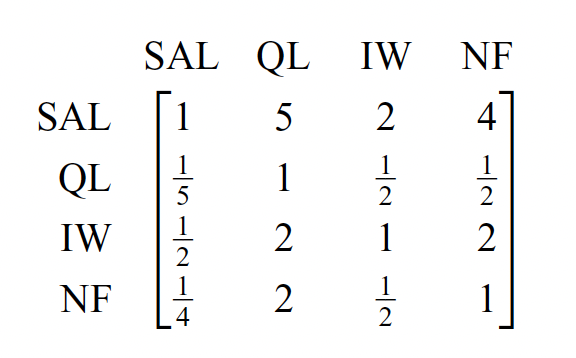

% Pairwise comparison matrix

A = [   1    5     2     4;

A =     1.0000    5.0000    2.0000    4.0000
    0.2000    1.0000    0.5000    0.5000
    0.5000    2.0000    1.0000    2.0000
    0.2500    2.0000    0.5000    1.0000


      0.2    1   0.5   0.5;
      0.5    2     1     2;
     0.25    2   0.5     1]

A_norm =     0.5128    0.5000    0.5000    0.5333
    0.1026    0.1000    0.1250    0.0667
    0.2564    0.2000    0.2500    0.2667
    0.1282    0.2000    0.1250    0.1333


Unfortunately, some of Jane’s pairwise comparisons are inconsistent. To illustrate the meaning of consistency, note that since $a_{13} =2$, she feels SAL is twice as important as IW. Since $a_{32} =2$, she also believes that IW is twice as important as QL. Consistency of preferences would imply that Jane should feel that SAL is 2(2)  = 4 times as important as QL. Since $a_{12} =5$, however, Jane believes that SAL is 5 times as important as QL. This shows that Jane’s pairwise comparisons exhibit a slight inconsistency. Slight inconsistencies are common and do not cause serious difficulties. An index that can be used to measure the consistency of Jane’s preferences will be discussed later.

Suppose there are $n$ objectives. Let $w_i$ be the weight given to objective $i$. 


$$\mathbf{w}=\left\lbrack \begin{array}{cccc}
w_1  & w_2  & \cdots  & w_n 
\end{array}\right\rbrack$$


Consider the system of *n* equations


$$\mathbf{A}{\mathit{\mathbf{w}}}^T =\Delta {\mathbf{w}}^T$$


where $\Delta$ is an unknown number and ${\mathbf{w}}^T$ is an unknown *n*-dimensional column vector.

If the decision maker’s comparisons do not deviate very much from perfect consistency, we would expect  $\Delta_{\max }$ to be close to $n$ and ${\mathbf{w}}_{\max }$ to be close to $\mathbf{w}$. Thomas Saaty verified that this intuition is indeed correct and suggested approximating $\mathbf{w}$ by ${\mathbf{w}}_{\max }$.

In what follows, we outline a simple method that can be used to approximate $\Delta_{\max }$ and ${\mathbf{w}}_{\max }$ and an index of consistency. To approximate ${\mathbf{w}}_{\max }$, we use the following two-step procedure:

**Step 1:** For each of $\mathbf{A}$’s columns, do the following. Divide each entry in column $i$ of $\mathbf{A}$ by the sum of the entries in column $i$. This yields a new matrix (call it ${\mathbf{A}}_{\textrm{norm}}$, for normalized) in which the sum of the entries in each column is 1. 

For Jane’s pairwise comparison matrix, step 1 yields

% Normalised pairwise comparison matrix

A_norm2 =     0.5128    0.5000    0.5000    0.5333
    0.1026    0.1000    0.1250    0.0667
    0.2564    0.2000    0.2500    0.2667
    0.1282    0.2000    0.1250    0.1333


A_norm = A/diag(sum(A,1))
% Normalised pairwise comparison matrix (another method)
A_norm2 = A./sum(A,1)

w_max =     0.5115
    0.0986
    0.2433
    0.1466


**Step 2: **To find an approximation to ${\mathbf{w}}_{\max }$ (to be used as our estimate of $\mathbf{w}$), proceed as follows. Estimate $w_i$ as the average of the entries in row $i$ of ${\mathbf{A}}_{\textrm{norm}}$. This yields 

% Find an approximation to w_max

ans = 1

w_max = mean(A_norm,2)
% sum of weight must be 1

W =    0.8623 + 0.0000i  -0.9535 + 0.0000i   0.6311 + 0.0000i   0.6311 + 0.0000i
   0.1644 + 0.0000i   0.0000 + 0.0000i  -0.2379 - 0.1704i  -0.2379 + 0.1704i
   0.4109 + 0.0000i   0.2860 + 0.0000i   0.4953 - 0.2819i   0.4953 + 0.2819i
   0.2460 + 0.0000i   0.0953 + 0.0000i  -0.1118 + 0.4229i  -0.1118 - 0.4229i


Delta =    4.0473 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0237 + 0.4370i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0237 - 0.4370i


sum(w_max)
% Use "eig" funtion to determine eigen vector of A

ans = 	1.0e+-14 *

    0.0888
    0.0555
    0.1332
   -0.0111


[W,Delta] = eig(A)
% Check eigen vector

w_exact =     0.5122
    0.0976
    0.2440
    0.1461


A*W(:,1) - Delta(1,1)*W(:,1)
% Determine exact weight
w_exact = W(:,1)/sum(W(:,1))

Intuitively, why does $w_1$ approximate the weight that objective 1 (salary) should be given? The percentage of the weight that SAL is given in pairwise comparisons of each objective to SAL is 0.5128. Similarly, 0.50 represents the percentage of total weight that SAL is given in pairwise comparisons of each objective to QL. Thus, we see that the four numbers averaged to obtain $w_1$ each represents in some way a measure of the total weight attached to SAL. Thus, averaging these numbers should give a good estimate of the percentage of the total weight that should be given to SAL.

## Checking for Consistency of Weight

Use the following four-step procedure to check for the consistency of the decision maker’s comparisons. (From now on, $\mathbf{w}$ denotes our estimate of the decision maker’s weights.)

**Step 1:** Compute


$$\mathbf{A}{\mathbf{w}}^T$$


**Step 2:** Compute 


$$\lambda =\frac{1}{n}\left(\mathbf{A}{\mathbf{w}}^T \cdot /\;{\mathbf{w}}^T \right)$$


**Step 3:** Compute the consistency index (CI) as follows:


$$\textrm{CI}=\frac{\lambda -n}{n-1}$$


**Step 4: **Compare CI to the random index (RI) for the appropriate value of $n$, shown in **Table 2**.

**Table 2:** Values of the Random Index (RI)

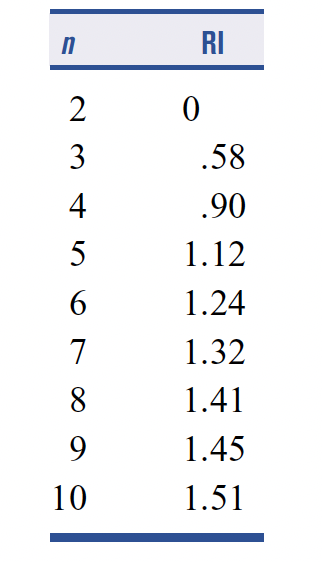

For a perfectly consistent decision maker, the *i*th entry in $\mathbf{A}{\mathbf{w}}^T =n$ (*i*th entry of ${\mathbf{w}}^T$). This implies that a perfectly consistent decision maker has CI = 0. The values of RI in Table 2 give the average value of CI if the entries in A were chosen at random, subject to the constraint that all diagonal entries must equal 1 and $a_{\textrm{ij}} =\frac{1}{a_{\textrm{ji}} }$.

If CI is sufficiently small, the decision maker’s comparisons are probably consistent enough to give useful estimates of the weights for his or her objective function. If  **CI/RI <  0.10**, the degree of consistency is satisfactory, but if  CI/RI >  0.10, serious inconsistencies may exist, and the AHP may not yield meaningful results. 

% Checking for Consistency


lambda = 4.0476

% Step 1 + Step 2
lambda = ones(1,4)*((A*w_max)./w_max)/4

CI = 0.0159

% Step 3
CI = (lambda-4)/3

RI = 0.9000

% Step 4

CIbyRI = 0.0176

RI = 0.90
CIbyRI = CI/RI

## Finding the Score of Each Alternative

We have now described how to determine the objective function weights that we earlier used to help Jane determine which job offer to accept. We now determine how well each job “satisfies” or “scores” on each objective. To determine these scores, we construct for each objective a pairwise comparison matrix in which the rows and columns are Jane’s possible decisions (in this case, job offers). For SAL, suppose we obtain the following pairwise comparison matrix:

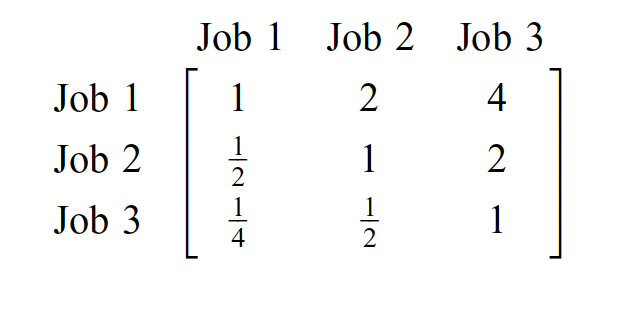

Thus, for example, with respect to salary, job 1 is better (between weakly and strongly) than job 3. We can now apply our procedure for generating weights to the SAL pairwise comparison matrix.

% Generating weights to the SAL pairwise comparison matrix
SAL = [   1    2    4;
        0.5    1    2;

SAL =     1.0000    2.0000    4.0000
    0.5000    1.0000    2.0000
    0.2500    0.5000    1.0000


       0.25  0.5    1]

SAL_norm =     0.5714    0.5714    0.5714
    0.2857    0.2857    0.2857
    0.1429    0.1429    0.1429


SAL_norm = SAL/diag(sum(SAL,1))

w_SAL =     0.5714
    0.2857
    0.1429


score_SAL = mean(SAL_norm,2)

These weights indicate how well each job “scores” with respect to the SAL objective. Since all three columns of the pairwise comparison matrix for salary exhibit perfect consistency.

Suppose Jane’s pairwise comparison matrix for quality of life (QL), interest in work (IW), and nearness to family (NF) are as follows:

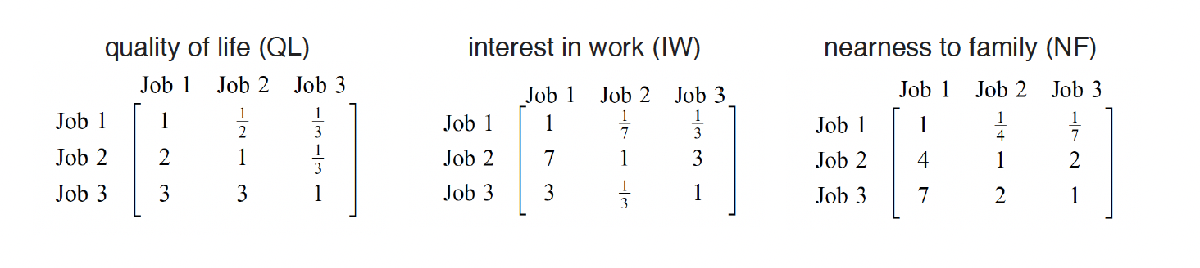

% Generating weights to the pairwise comparison matrices of QL, IW and NF
QL  = [   1  0.5  1/3;
          2    1  1/3;

QL =     1.0000    0.5000    0.3333
    2.0000    1.0000    0.3333
    3.0000    3.0000    1.0000


          3    3    1]

QL_norm =     0.1667    0.1111    0.2000
    0.3333    0.2222    0.2000
    0.5000    0.6667    0.6000


QL_norm = QL/diag(sum(QL,1))

w_QL =     0.1593
    0.2519
    0.5889


score_QL = mean(QL_norm,2)
IW  = [   1  1/7  1/3;
          7    1    3;

IW =     1.0000    0.1429    0.3333
    7.0000    1.0000    3.0000
    3.0000    0.3333    1.0000


          3  1/3    1]

IW_norm =     0.0909    0.0968    0.0769
    0.6364    0.6774    0.6923
    0.2727    0.2258    0.2308


IW_norm = IW/diag(sum(IW,1))

w_IW =     0.0882
    0.6687
    0.2431


score_IW = mean(IW_norm,2)
NF  = [   1 0.25  1/7;
          4    1    2;

NF =     1.0000    0.2500    0.1429
    4.0000    1.0000    2.0000
    7.0000    2.0000    1.0000


          7    2    1]

NF_norm =     0.0833    0.0769    0.0455
    0.3333    0.3077    0.6364
    0.5833    0.6154    0.3182


NF_norm = NF/diag(sum(NF,1))

w_NF =     0.0686
    0.4258
    0.5056


score_NF = mean(NF_norm,2)

Given Jane’s weights and the score of each job on each objective, choose the job offer with the highest overall score. Note that the overall score gives more weight to a job offer’s score on the more important objectives.

% Computing each job’s overall score

ans =     0.5714    0.1593    0.0882    0.0686
    0.2857    0.2519    0.6687    0.4258
    0.1429    0.5889    0.2431    0.5056


job_score =     0.3395
    0.3961
    0.2644


job_score = [score_SAL, score_QL, score_IW, score_NF]*w_max

Thus, the AHP would indicate that job offer 2 is most preferred, followed by job offer 1, with job offer 3 the least preferred.

We close by noting that AHP has been applied by decision makers in countless areas, including accounting, finance, marketing, energy resource planning, microcomputer selection, sociology, architecture, and political science.

## Checking for Consistency of Scores

% Score of SAL
[V_SAL, D_SAL] = eig(SAL)

V_SAL =     0.8729   -0.0000    0.8426
    0.4364   -0.8944   -0.5355
    0.2182    0.4472    0.0571


D_SAL =     3.0000         0         0
         0    0.0000         0
         0         0   -0.0000


% CI/RI of SAL
CIbyRI_SAL = (D_SAL(1,1)-3)/2/0.58

CIbyRI_SAL = -7.6567e-16

% Score of QL
[V_QL, D_QL] = eig(QL)

V_QL =    0.2370 + 0.0000i   0.1185 + 0.2052i   0.1185 - 0.2052i
   0.3762 + 0.0000i   0.1881 - 0.3258i   0.1881 + 0.3258i
   0.8957 + 0.0000i  -0.8957 + 0.0000i  -0.8957 + 0.0000i


D_QL =    3.0536 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0268 + 0.4038i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0268 - 0.4038i


% CI/RI of QL
CIbyRI_QL = (D_QL(1,1)-3)/2/0.58

CIbyRI_QL = 0.0462

% Score of IW
[V_IW, D_IW] = eig(IW)

V_IW =    0.1226 + 0.0000i  -0.0613 - 0.1062i  -0.0613 + 0.1062i
   0.9331 + 0.0000i   0.9331 + 0.0000i   0.9331 + 0.0000i
   0.3382 + 0.0000i  -0.1691 + 0.2929i  -0.1691 - 0.2929i


D_IW =    3.0070 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0035 + 0.1453i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0035 - 0.1453i


% CI/RI of IW
CIbyRI_IW = (D_IW(1,1)-3)/2/0.58

CIbyRI_IW = 0.0061

% Score of NF
[V_NF, D_NF] = eig(NF)

V_NF =    -0.0985   -0.2899    0.0569
   -0.6720    0.9438   -0.7820
   -0.7340    0.1588    0.6207


D_NF =     3.7705         0         0
         0    0.1078         0
         0         0   -0.8784


% CI/RI of NF
CIbyRI_NF = (D_NF(1,1)-3)/2/0.58

CIbyRI_NF = 0.6642

## HOMEWORK (2-Hierarchy)

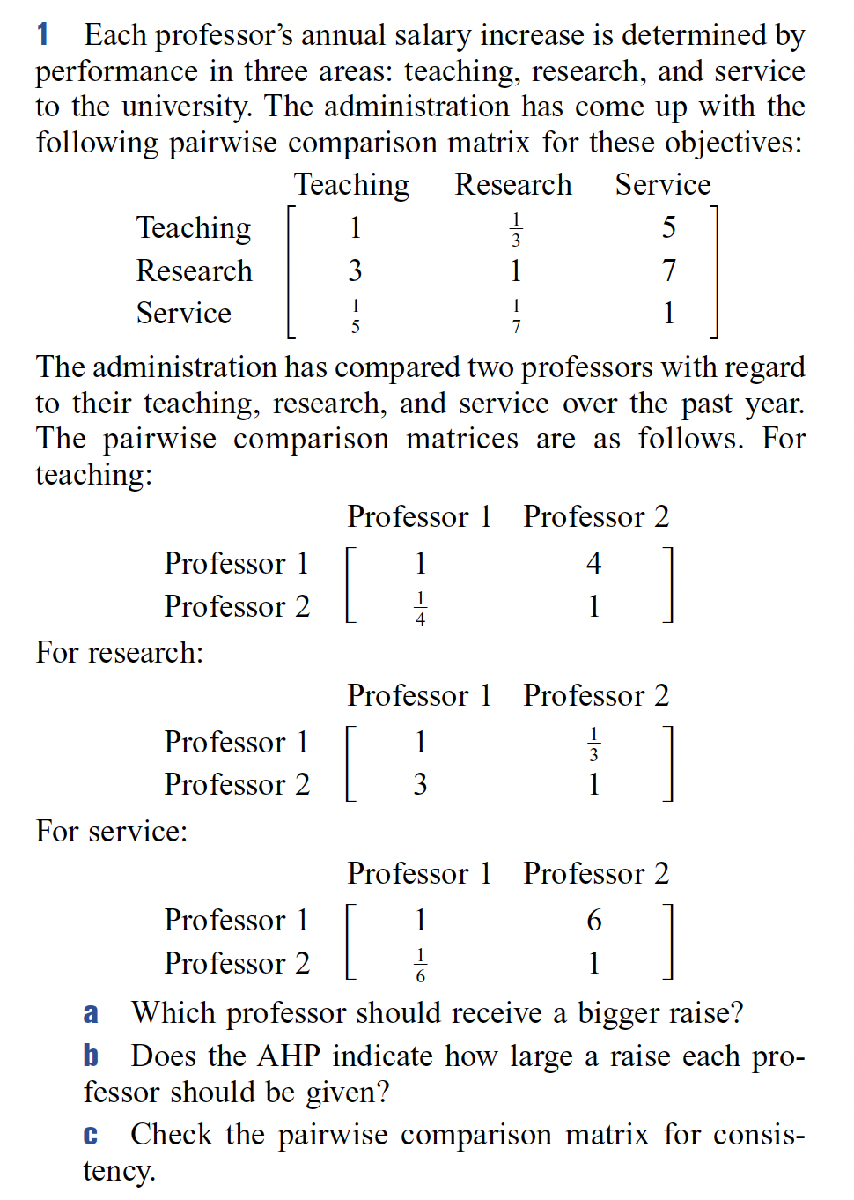

### Pairwise comparison matrix

% Pairwise comparison matrix
A2 = [  1    1/3     5;
        3      1     7;
      1/5    1/7     1]
% Normalised pairwise comparison matrix

A2 =     1.0000    0.3333    5.0000
    3.0000    1.0000    7.0000
    0.2000    0.1429    1.0000


A2_norm = A2/diag(sum(A2,1))
% Find an approximation to w_max

A2_norm =     0.2381    0.2258    0.3846
    0.7143    0.6774    0.5385
    0.0476    0.0968    0.0769


w2_max = mean(A2_norm,2)
% Use "eig" funtion to determine eigen vector of A

w2_max =     0.2828
    0.6434
    0.0738


[W2,Delta2] = eig(A2)
% Determine exact weight

W2 =    0.3928 + 0.0000i  -0.1964 + 0.3402i  -0.1964 - 0.3402i
   0.9140 + 0.0000i   0.9140 + 0.0000i   0.9140 + 0.0000i
   0.1013 + 0.0000i  -0.0506 - 0.0877i  -0.0506 + 0.0877i


Delta2 =    3.0649 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0324 + 0.4448i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0324 - 0.4448i


w2_exact = W2(:,1)/sum(W2(:,1))
% Checking for Consistency

w2_exact =     0.2790
    0.6491
    0.0719



% Step 1 + Step 2
lambda2 = ones(1,3)*((A2*w2_max)./w2_max)/3
% Step 3

lambda2 = 3.0655

CI2 = (lambda2-3)/2
% Step 4

CI2 = 0.0328

RI2 = 0.58
CI2byRI2 = CI2/RI2

RI2 = 0.5800

CI2byRI2 = 0.0565

### Teaching skill

% Generating weights to the teacing skill
teach = [   1    4;
         0.25    1]
teach_norm = teach/diag(sum(teach,1))

teach =     1.0000    4.0000
    0.2500    1.0000


score_teach = mean(teach_norm,2)

teach_norm =     0.8000    0.8000
    0.2000    0.2000


score_teach =     0.8000
    0.2000


### Research

% Generating weights to the reserarch achievement 
research = [   1    1/3;
               3      1]
research_norm = research/diag(sum(research,1))

research =     1.0000    0.3333
    3.0000    1.0000


score_research = mean(research_norm,2)

research_norm =     0.2500    0.2500
    0.7500    0.7500


score_research =     0.2500
    0.7500


### Service to University

% Generating weights to the service to university 
service = [   1    6;
            1/6    1]
service_norm = service/diag(sum(service,1))

service =     1.0000    6.0000
    0.1667    1.0000


score_service = mean(service_norm,2)

service_norm =     0.8571    0.8571
    0.1429    0.1429


score_service =     0.8571
    0.1429


### Final decision

% Computing each professor’s overall score
prof_score = [score_teach, score_research, score_service]*w2_max

prof_score =     0.4504
    0.5496


### Answer

- Professor 2 should receive the bigger raise.

- No.

- Pairwise comparison matrix is consistent.

## HOMEWORK (3-Hierarchy)

A professor of political science wants to predict the outcome of a school board election. Three candidates, Ivy (I), Bahrn (B), and Smith (S), are running for one position. There are three categories of voters: left (L), center (C), and right (R). The candidates are judged based on three factors: educational experience (E), stand on issues (S), and personal character (P). The following are the comparison matrices for the first hierarchy of left, center, and right:

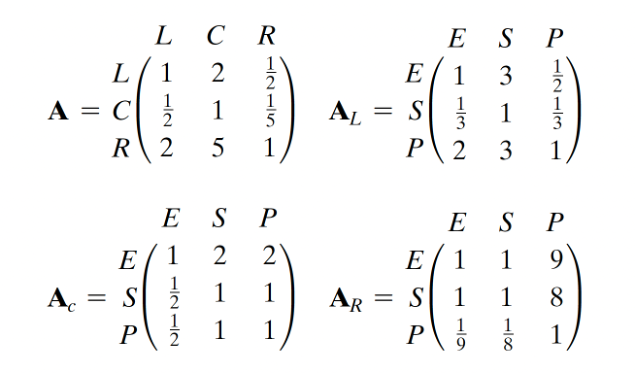

The professor generated nine more comparison matrices for the second hierarchy representing experience (E), stand on issues (S), and personal character (P). AHP was then used to reduce these matrices to the following relative weights:

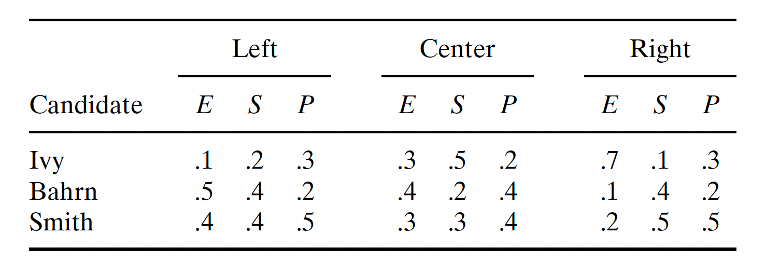

Determine the winning candidate, and assess the consistency of the decision.

A3 = [  1     2   0.5;
        0.5   1   0.2;
        2     5     1]

A3 =     1.0000    2.0000    0.5000
    0.5000    1.0000    0.2000
    2.0000    5.0000    1.0000



% Normalised pairwise comparison matrix
A3_norm = A3/diag(sum(A3,1))

A3_norm =     0.2857    0.2500    0.2941
    0.1429    0.1250    0.1176
    0.5714    0.6250    0.5882


% Find an approximation to w_max
w3_max = mean(A3_norm,2)

w3_max =     0.2766
    0.1285
    0.5949


% Use "eig" funtion to determine eigen vector of A
[W3,DeltA3] = eig(A3)

W3 =   -0.4132 + 0.0000i  -0.2066 - 0.3578i  -0.2066 + 0.3578i
  -0.1918 + 0.0000i  -0.0959 + 0.1661i  -0.0959 - 0.1661i
  -0.8902 + 0.0000i   0.8902 + 0.0000i   0.8902 + 0.0000i


DeltA3 =    3.0055 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0028 + 0.1290i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0028 - 0.1290i


% Determine exact weight
w3_exact = W3(:,1)/sum(W3(:,1))

w3_exact =     0.2764
    0.1283
    0.5954



% Checking for Consistency
% Step 1 + Step 2
lambda3 = ones(1,3)*((A3*w3_max)./w3_max)/3

lambda3 = 3.0055

% Step 3
CI3 = (lambda3-3)/2

CI3 = 0.0028

% Step 4
RI3 = 0.58

RI3 = 0.5800

CI3byRI3 = CI3/RI3

CI3byRI3 = 0.0048

### Left voters

% Generating weights to the left voters
left = [  1   3   0.5;
        1/3   1   1/3;
          2   3     1]

left =     1.0000    3.0000    0.5000
    0.3333    1.0000    0.3333
    2.0000    3.0000    1.0000


left_norm = left/diag(sum(left,1))

left_norm =     0.3000    0.4286    0.2727
    0.1000    0.1429    0.1818
    0.6000    0.4286    0.5455


score_left = mean(left_norm,2)

score_left =     0.3338
    0.1416
    0.5247


### Center voters

% Generating weights to the center voters 
center = [  1   2   2;
          0.5   1   1;
          0.5   1   1]

center =     1.0000    2.0000    2.0000
    0.5000    1.0000    1.0000
    0.5000    1.0000    1.0000


center_norm = center/diag(sum(center,1))

center_norm =     0.5000    0.5000    0.5000
    0.2500    0.2500    0.2500
    0.2500    0.2500    0.2500


score_center = mean(center_norm,2)

score_center =     0.5000
    0.2500
    0.2500


### Right voters

% Generating weights to the right voters
right = [  1   1   9;
           1   1   8;
         1/9 1/8   1]

right =     1.0000    1.0000    9.0000
    1.0000    1.0000    8.0000
    0.1111    0.1250    1.0000


right_norm = right/diag(sum(right,1))

right_norm =     0.4737    0.4706    0.5000
    0.4737    0.4706    0.4444
    0.0526    0.0588    0.0556


score_right = mean(right_norm,2)

score_right =     0.4814
    0.4629
    0.0557


### Final decision

% Computing each candidate’s overall score
Ivy =   [0.1  0.2  0.3;
         0.3  0.5  0.2;
         0.7  0.1  0.3]

Ivy =     0.1000    0.2000    0.3000
    0.3000    0.5000    0.2000
    0.7000    0.1000    0.3000



Bahrn = [0.5  0.4  0.2;
         0.4  0.2  0.4;
         0.1  0.4  0.2]

Bahrn =     0.5000    0.4000    0.2000
    0.4000    0.2000    0.4000
    0.1000    0.4000    0.2000



Smith = [0.4  0.4  0.5;
         0.3  0.3  0.4;
         0.2  0.5  0.5]

Smith =     0.4000    0.4000    0.5000
    0.3000    0.3000    0.4000
    0.2000    0.5000    0.5000



Ivy_Score =   [Ivy(1,:)*score_left, Ivy(2,:)*score_center, Ivy(3,:)*score_right]*w3_max

Ivy_Score = 0.3403

Bahrn_Score = [Bahrn(1,:)*score_left, Bahrn(2,:)*score_center, Bahrn(3,:)*score_right]*w3_max

Bahrn_Score = 0.2812

Smith_Score = [Smith(1,:)*score_left, Smith(2,:)*score_center, Smith(3,:)*score_right]*w3_max

Smith_Score = 0.3784


Ivy_Score + Bahrn_Score + Smith_Score % Must be 1

ans = 1.0000


% Another method

Left =   [0.1  0.2  0.3;
          0.5  0.4  0.2;
          0.4  0.4  0.5]

Left =     0.1000    0.2000    0.3000
    0.5000    0.4000    0.2000
    0.4000    0.4000    0.5000



Center = [0.3  0.5  0.2;
          0.4  0.2  0.4;
          0.3  0.3  0.4]

Center =     0.3000    0.5000    0.2000
    0.4000    0.2000    0.4000
    0.3000    0.3000    0.4000



Right = [0.7  0.1  0.3
         0.1  0.4  0.2
         0.2  0.5  0.5]

Right =     0.7000    0.1000    0.3000
    0.1000    0.4000    0.2000
    0.2000    0.5000    0.5000



Candidate_Score = [Left*score_left, Center*score_center, Right*score_right]*w3_max

Candidate_Score =     0.3403
    0.2812
    0.3784


### Answer

The winning candidate is Smith.